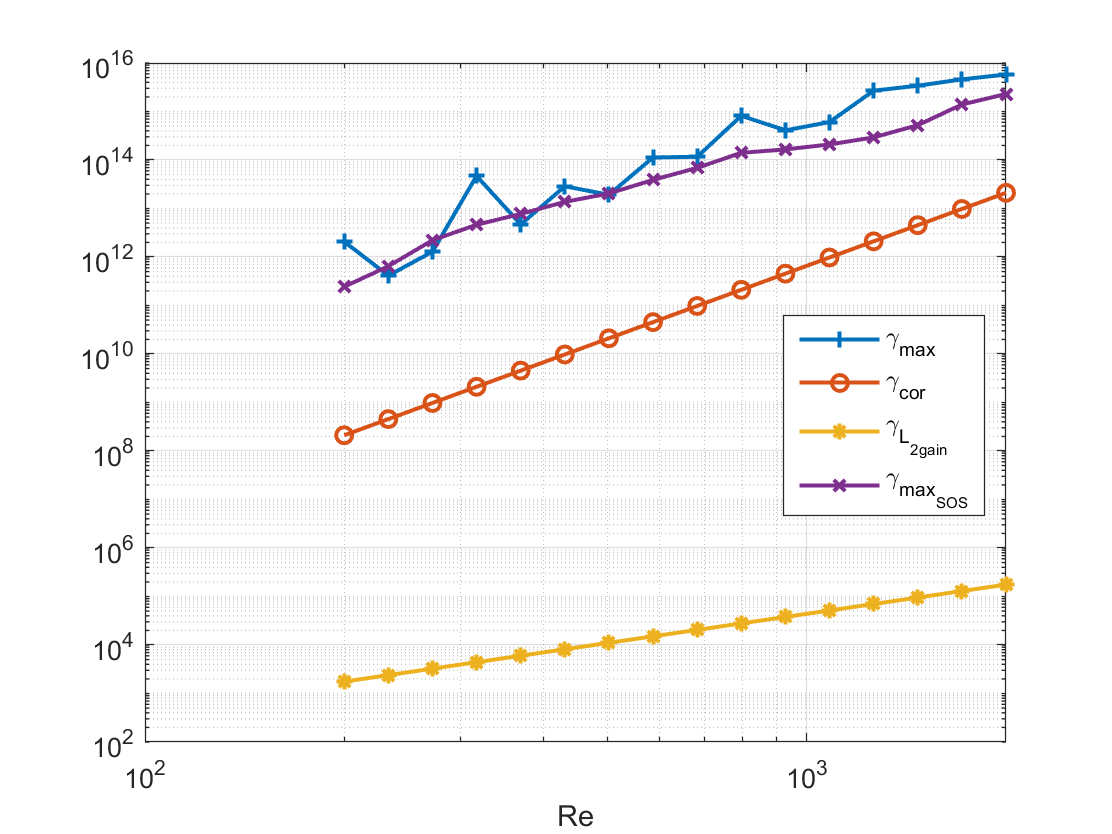


colors = lines(16);
line_styles = ["-","--","-.",":"];
markers = {'+', 'o', '*', 'x', 's', 'd', '^', 'v', '>', '<', 'p', 'h'};
figure
loglog(Re_list, Gamma_theorem_max(:,:), '-o', 'LineWidth', 1.5,'Color', colors(1, :), 'Marker', markers{1});
hold on;
loglog(Re_list, gamma_cor(:, :), '-s', 'LineWidth', 1.5, 'Color', colors(2, :), 'Marker', markers{2});
loglog(Re_list, L2_gain(:, :), '-s', 'LineWidth', 1.5, 'Color', colors(3, :), 'Marker', markers{3});
loglog(Re_list, Gamma_theorem_max_SOS(:, :), '-s', 'LineWidth', 1.5, 'Color', colors(4, :), 'Marker', markers{4});
hold off;
xlim([1e2, 2000]);  
xlabel('Re');
legend('\gamma_{max}','\gamma_{cor}', '\gamma_{L_{2gain}}','\gamma_{max_{SOS}}')
grid on;

legend("Position",[0.70417,0.41508,0.18214,0.17262])

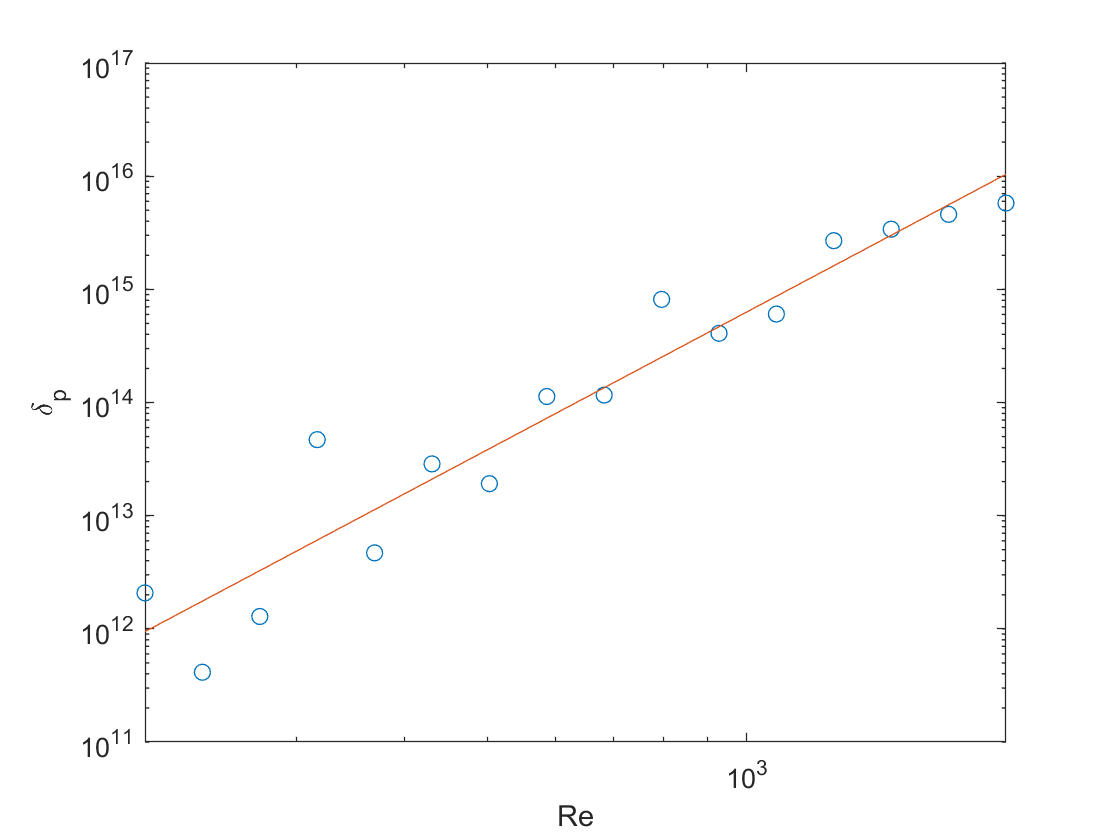




log_Re_list = log10(Re_list);
log_Gamma_theorem_max = log10(Gamma_theorem_max);
log_Gamma_theorem_max_SOS = log10(Gamma_theorem_max_SOS);
log_L2_gain = log10(L2_gain);
log_gamma_cor = log10(gamma_cor);

% Least Square: Gamma_theorem_max
coeffs = polyfit(log_Re_list, log_Gamma_theorem_max, 1);
sigma_theorem = coeffs(1);
A_log_theorem = coeffs(2);
figure;
loglog(Re_list, Gamma_theorem_max, 'o'); hold on;
fit_line = 10.^polyval(coeffs, log_Re_list);
loglog(Re_list, fit_line, '-');
xlabel('Re');
ylabel('\delta_{p}');

disp(['Scaling exponent (sigma): ', num2str(sigma_theorem)]);

Scaling exponent (sigma): 4.041


disp(['Intercept (A): ', num2str(A_log_theorem)]);

Intercept (A): 2.6771


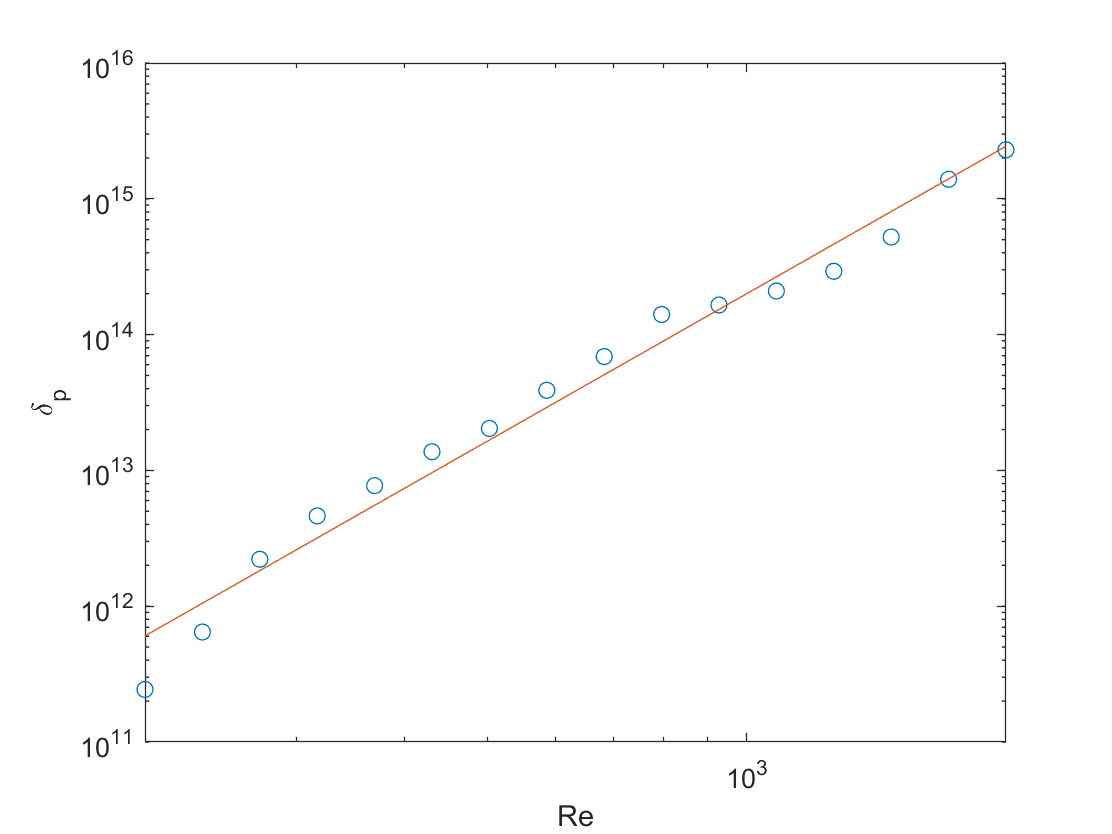



coeffs = polyfit(log_Re_list, log_Gamma_theorem_max_SOS, 1);
sigma_theorem = coeffs(1);
A_log_theorem = coeffs(2);
figure;
loglog(Re_list, Gamma_theorem_max_SOS, 'o'); hold on;
fit_line = 10.^polyval(coeffs, log_Re_list);
loglog(Re_list, fit_line, '-');
xlabel('Re');
ylabel('\delta_{p}');

disp(['Scaling exponent (sigma): ', num2str(sigma_theorem)]);

Scaling exponent (sigma): 3.6058


disp(['Intercept (A): ', num2str(A_log_theorem)]);

Intercept (A): 3.4844


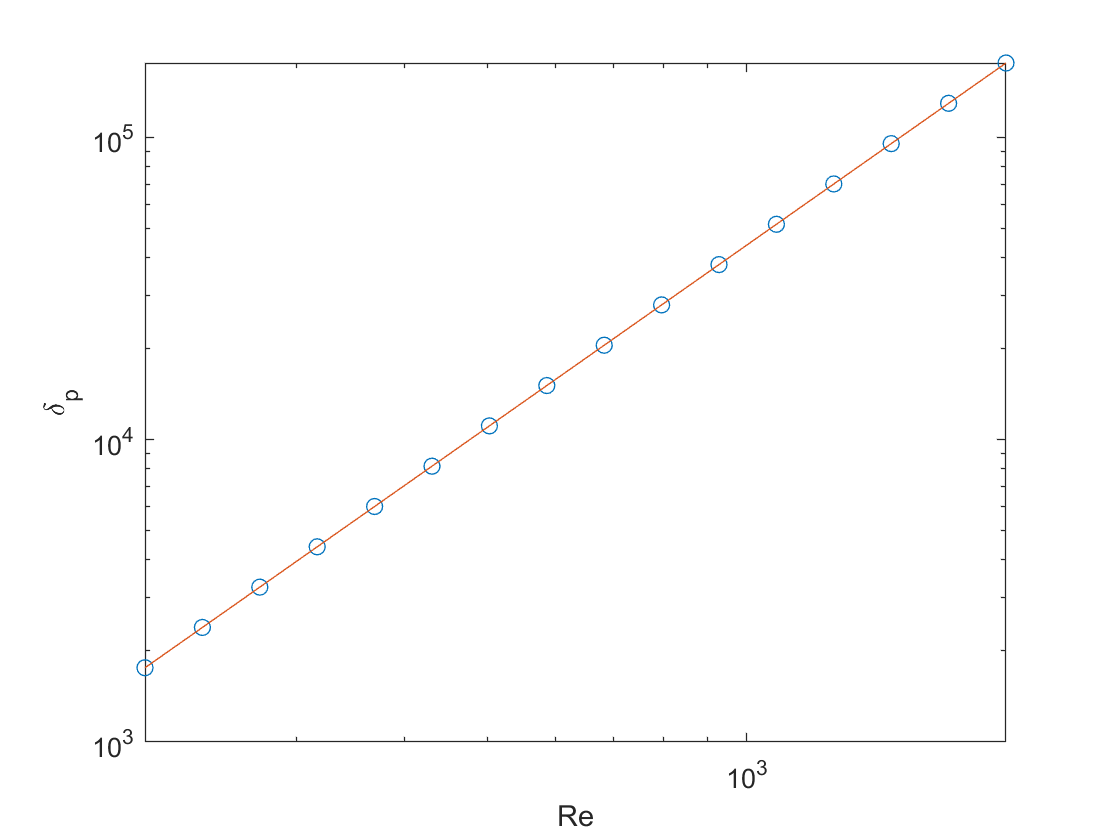



coeffs = polyfit(log_Re_list, log_L2_gain, 1);
sigma_theorem = coeffs(1);
A_log_theorem = coeffs(2);
figure;
loglog(Re_list, L2_gain, 'o'); hold on;
fit_line = 10.^polyval(coeffs, log_Re_list);
loglog(Re_list, fit_line, '-');
xlabel('Re');
ylabel('\delta_{p}');

disp(['Scaling exponent (sigma): ', num2str(sigma_theorem)]);

Scaling exponent (sigma): 1.9999


disp(['Intercept (A): ', num2str(A_log_theorem)]);

Intercept (A): -1.3562


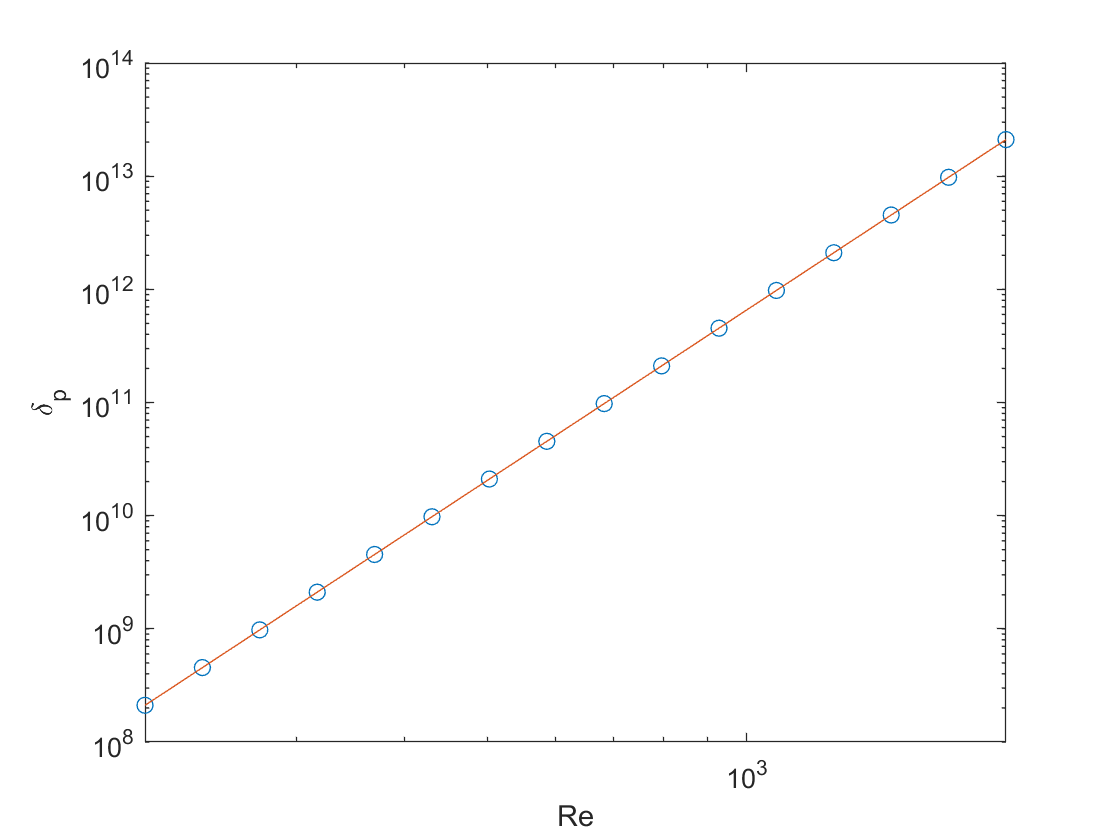


coeffs = polyfit(log_Re_list, log_gamma_cor, 1);
sigma_theorem = coeffs(1);
A_log_theorem = coeffs(2);
figure;
loglog(Re_list, gamma_cor, 'o'); hold on;
fit_line = 10.^polyval(coeffs, log_Re_list);
loglog(Re_list, fit_line, '-');
xlabel('Re');
ylabel('\delta_{p}');

disp(['Scaling exponent (sigma): ', num2str(sigma_theorem)]);

Scaling exponent (sigma): 4.9991


disp(['Intercept (A): ', num2str(A_log_theorem)]);

Intercept (A): -3.179




figure;
hold on;

% Gamma_theorem_max
coeffs1 = polyfit(log_Re_list, log_Gamma_theorem_max, 1);
fit_line1 = 10.^polyval(coeffs1, log_Re_list);
loglog(Re_list, Gamma_theorem_max, 'ro', 'DisplayName', 'Data point of $\gamma_{max}$','Color', colors(1, :), 'Marker', markers{1},'LineWidth', 1.5);
loglog(Re_list, fit_line1, 'r-', 'DisplayName', 'Least square fit of $\gamma_{max}$', 'LineWidth', 1.5,'Color', colors(1, :));
disp(['Scaling exponent (sigma): ', num2str(coeffs1(1))]);

Scaling exponent (sigma): 4.041


disp(['Intercept (A): ', num2str(coeffs1(2))]);

Intercept (A): 2.6771



% Gamma_theorem_max_SOS
coeffs2 = polyfit(log_Re_list, log_Gamma_theorem_max_SOS, 1);
fit_line2 = 10.^polyval(coeffs2, log_Re_list);
loglog(Re_list, Gamma_theorem_max_SOS, 'bo', 'DisplayName', 'Data point of $\gamma_{max_{SOS}}$','Color', colors(2, :), 'Marker', markers{2},'LineWidth', 1.5);
loglog(Re_list, fit_line2, 'b-', 'DisplayName', 'Least square fit of $\gamma_{max_{SOS}}$', 'LineWidth', 1.5,'Color', colors(2, :));
disp(['Scaling exponent (sigma): ', num2str(coeffs2(1))]);

Scaling exponent (sigma): 3.6058


disp(['Intercept (A): ', num2str(coeffs2(2))]);

Intercept (A): 3.4844



% L2_gain
coeffs3 = polyfit(log_Re_list, log_L2_gain, 1);
fit_line3 = 10.^polyval(coeffs3, log_Re_list);
loglog(Re_list, L2_gain, 'go', 'DisplayName', 'Data point of $\gamma_{\mathcal{L}_2}$','Color', colors(3, :), 'Marker', markers{3},'LineWidth', 1.5);
loglog(Re_list, fit_line3, 'g-', 'DisplayName', 'Least square fit of $\gamma_{\mathcal{L}_2}$','LineWidth', 1.5,'Color', colors(3, :));
disp(['Scaling exponent (sigma): ', num2str(coeffs3(1))]);

Scaling exponent (sigma): 1.9999


disp(['Intercept (A): ', num2str(coeffs3(2))]);

Intercept (A): -1.3562



% gamma_cor
coeffs4 = polyfit(log_Re_list, log_gamma_cor, 1);
fit_line4 = 10.^polyval(coeffs4, log_Re_list);
loglog(Re_list, gamma_cor, 'ko', 'DisplayName', 'Data point of $\gamma_{cor}$','Color', colors(4, :), 'Marker', markers{4},'LineWidth', 1.5);
loglog(Re_list, fit_line4, 'k-', 'DisplayName', 'Least square fit of $\gamma_{cor}$','LineWidth', 1.5,'Color', colors(4, :));
disp(['Scaling exponent (sigma): ', num2str(coeffs4(1))]);

Scaling exponent (sigma): 4.9991


disp(['Intercept (A): ', num2str(coeffs4(2))]);

Intercept (A): -3.179


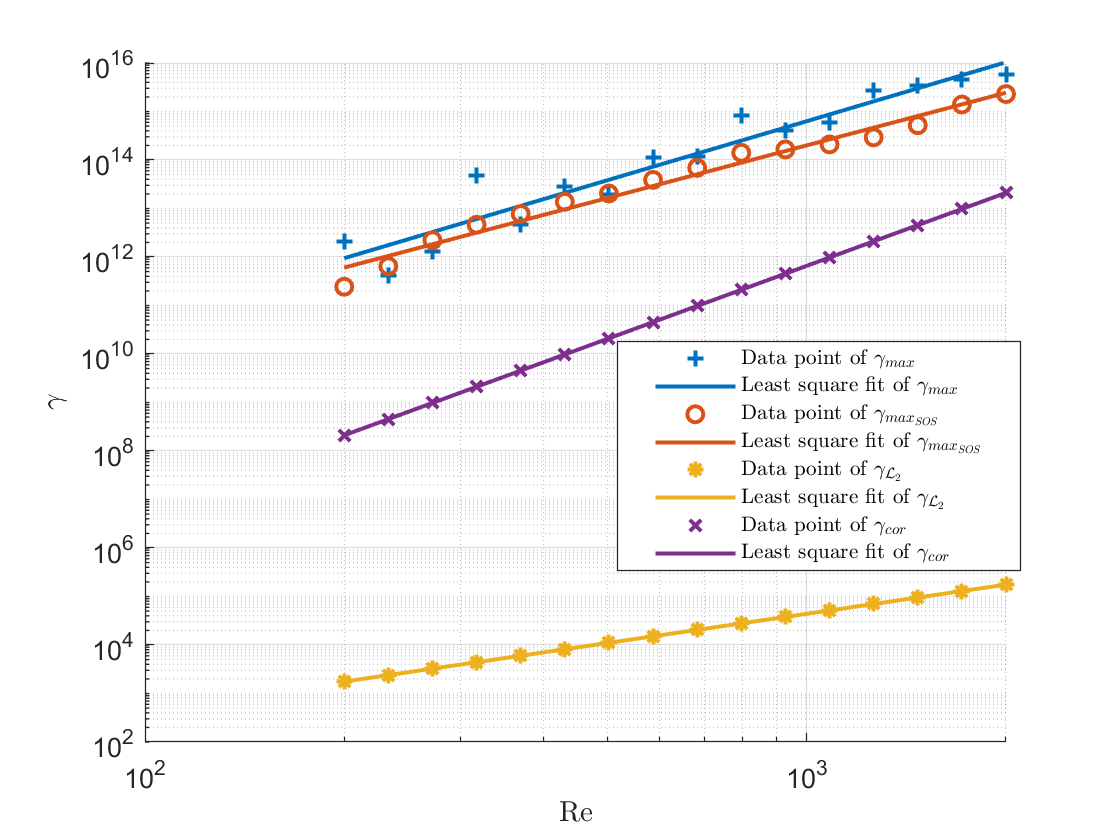


xlabel('Re','Interpreter', 'latex');
ylabel('$\gamma$','Interpreter', 'latex');
legend('Location','best','Fontsize',8,'Interpreter', 'latex');
set(gca, 'XScale', 'log', 'YScale', 'log');
grid on;
hold off;


xlim([100 2000])
ylim([100 10000000000000000])
legend("Position",[0.55515,0.31593,0.36339,0.275])